clc, clear

addpath('functions')
% net = googlenet;
load('net4.mat')
net_google = googlenet;

% imds_set 생성

[imds_set, label_set] = generate_image_set('..\images\train\');

% 각 클래스별 학습
featureLayer = 'loss3-classifier';
classifiers = train_concat_model(net,imds_set,featureLayer,false);
classifiers_google = train_concat_model(net_google,imds_set,featureLayer,false);

% 특징 추출
imds = imageDatastore('..\images\train\',"IncludeSubfolders",true,'LabelSource',"foldernames");
result = predict_concat_model(net, classifiers,imds,label_set,featureLayer,false);
result_google = predict_concat_model(net_google, classifiers_google,imds,label_set,featureLayer,false);

X = table2array(result(:,1:end-1));
y = table2array(result(:,end));
X_google = table2array(result_google(:,1:end-1));
y_google = table2array(result_google(:,end));

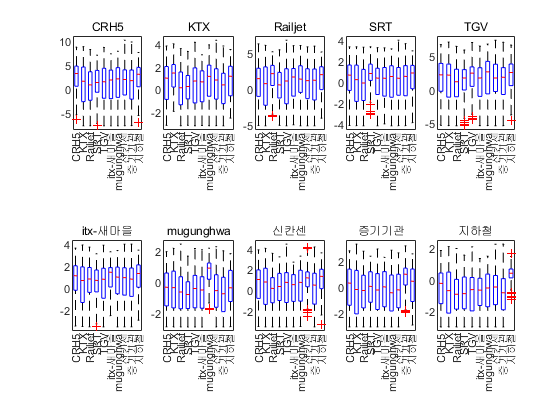


class_list = unique(y);

for i=1:length(class_list)
    class_name = class_list(i);
    feature_data = X(:,i);
    
    subplot(2,5,i)
    boxplot(feature_data,y)
    title(class_list(i))
    xtickangle(90)
end

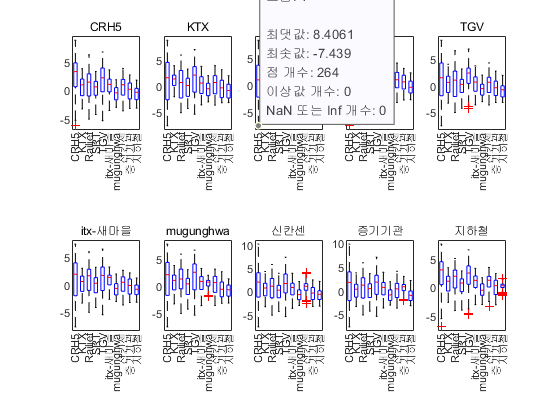

for i=1:length(class_list)
    class_name = class_list(i);
    idx = find(y == class_name);
    subplot(2,5,i)
    boxplot(X(idx,:))
    title(class_name)
    xticklabels(class_list)
    xtickangle(90)
end


% test 정확도
imds_te = imageDatastore('..\images\validation\',"IncludeSubfolders",true,'LabelSource',"foldernames");


result_test = predict_concat_model(net, classifiers,imds_te,label_set,featureLayer,false);
X_test = table2array(result_test(:,1:end-1));
y_test = table2array(result_test(:,end));

result_test_google = predict_concat_model(net_google, classifiers_google,imds_te,label_set,featureLayer,false);
X_test_google = table2array(result_test_google(:,1:end-1));
y_test_google = table2array(result_test_google(:,end));

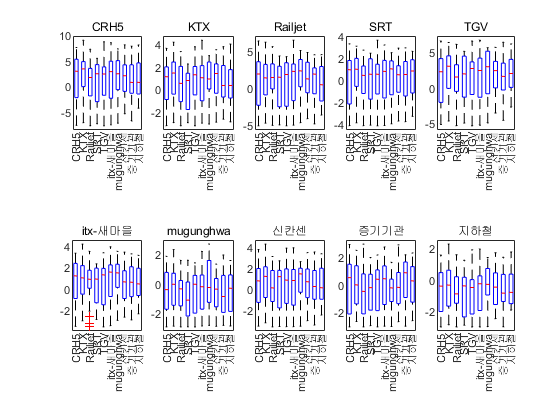

figure
class_list = unique(y_test);

for i=1:length(class_list)
    feature_data = X_test(:,i);
    
    subplot(2,5,i)
    boxplot(feature_data,y_test)
    title(class_list(i))
    xtickangle(90)
end

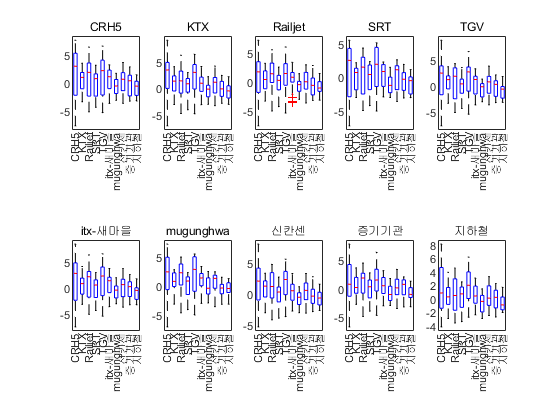

figure
for i=1:length(class_list)
    class_name = class_list(i);
    idx = find(y_test == class_name);
    subplot(2,5,i)
    boxplot(X_test(idx,:))
    title(class_name)
    xticklabels(class_list)
    xtickangle(90)
end

path_train = 'C:\Users\a6672\Documents\MATLAB\Examples\R2020b\202102w3\hist_train';
figure
for i=1:10
    for j=1:10
        class_name = class_list(i);
        idx = find(y==class_name);
        class_data = X(idx,:);
        if class_name==class_list(j)
            histogram(class_data(:,j),'FaceColor','r')
        else
            histogram(class_data(:,j))
        end
        title_name = strcat('(train) ',string(class_list(j))," points of ",string(class_list(i)));
        title(title_name);
        saveas(gcf,strcat(path_train,'\',title_name,'.png'))
    end
end


path_test = 'C:\Users\a6672\Documents\MATLAB\Examples\R2020b\202102w3\hist_test';
figure
for i=1:10
    for j=1:10
        class_name = class_list(i);
        idx = find(y_test==class_name);
        class_data = X_test(idx,:);
        if class_name==class_list(j)
            histogram(class_data(:,j),'FaceColor','r')
        else
            histogram(class_data(:,j))
        end
        title_name = strcat('(test) ',string(class_list(j))," points of ",string(class_list(i)));
        title(title_name);
        saveas(gcf,strcat(path_test,'\',title_name,'.png'))
    end
end

figure
class_list = unique(y_test);
j_s = [1,2,3,4,5,11,12,13,14,15];
for i=1:length(class_list)
    subplot(4,5,j_s(i))
    idx = find(y==class_list(i));
    feature_data = X(idx,:);
    plot(quantile(feature_data,0.75),'r-')
    hold on
    idx_test = find(y_test==class_list(i));
    feature_data_test = X_test(idx_test,:);
    plot(quantile(feature_data_test,0.75),'k--')
    xticks(1:10)
    xlim([0,11])
    xticklabels(class_list)
    xtickangle(90)
    title(strcat(string(class_list(i)),': 3rd qurtile points'))
    xline(i,'b')
    if i==1
        legend('train','test')
    end
    hold off
    
    subplot(4,5,j_s(i)+5)
    idx = find(y_google==class_list(i));
    feature_data = X_google(idx,:);
    plot(quantile(feature_data,0.75),'r-')
    hold on
    idx_test = find(y_test_google==class_list(i));
    feature_data_test = X_test_google(idx_test,:);
    plot(quantile(feature_data_test,0.75),'k--')
    xticks(1:10)
    xlim([0,11])
    xticklabels(class_list)
    xtickangle(90)
    title(strcat(string(class_list(i)),': 3rd qurtile googlenet points'))
    xline(i,'b')
    hold off
    
end
